%load Data and exclusion files
load(fullfile('..','data','data_struct.mat'));
subjects = subjects(relevant_ss);
%the excludeSubjects scrips works block-wise. To convert to a trial-wise inclusion list, 
%replicate each entry 40 times. 
included_trials = rectpulse((toExclude'==0&toExcludeFromConfAnalyses'==0)+0,40)';
%this is from colorbrewer: http://colorbrewer2.org/#type=sequential&scheme=BuGn&n=3
load('cb.mat')

## Make figure 2

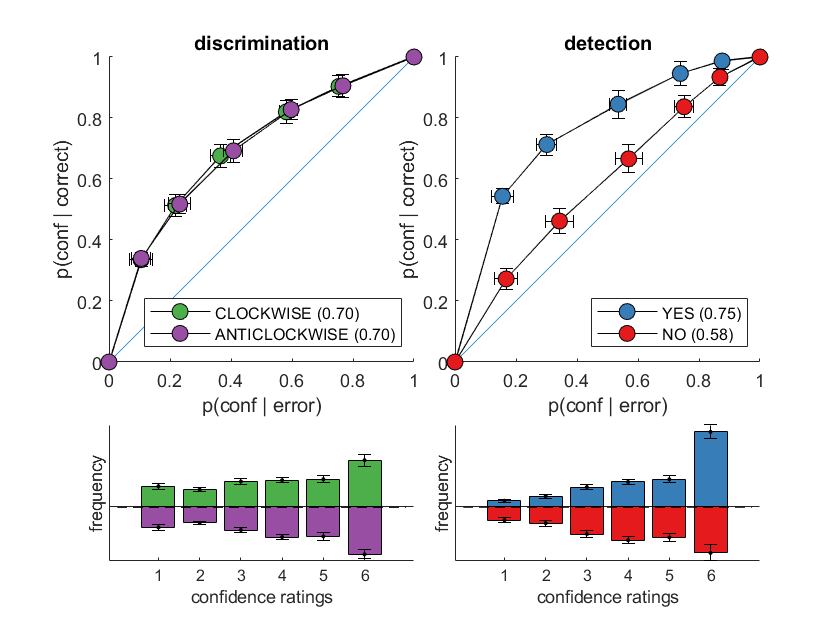

meanAccDet = [];
meanAccDis = [];
mean_dprimeDet = [];
mean_dprimeDis = [];
meanAUROCDet = [];
meanAUROCDis = [];

for s = 1:length(subjects)

    subject = data_struct(subjects{s});
    
    AccDet = subject.DetCorrect(find(included_trials(s,:)));
    AccDis = subject.DisCorrect(find(included_trials(s,:)));
    
    dprimeDet = norminv(nanmean(subject.DetResp(subject.DetSignal == 1 & included_trials(s,:)'))) - ...
        norminv(nanmean(subject.DetResp(subject.DetSignal == 0 & included_trials(s,:)')));
    
    dprimeDis = norminv(nanmean(subject.DisResp(subject.DisSignal == 1 & included_trials(s,:)'))) - ...
        norminv(nanmean(subject.DisResp(subject.DisSignal == 0 & included_trials(s,:)')));
    
    AUROCDet = extractAUROC(subject.DetSignal,subject.DetResp,subject.DetConf);
    
    AUROCDis = extractAUROC(subject.DisSignal,subject.DisResp,subject.DisConf);
    
    meanAccDet(s) = nanmean(AccDet);
    meanAccDis(s) = nanmean(AccDis);

    mean_dprimeDet(s) = dprimeDet;
    mean_dprimeDis(s) = dprimeDis;
    
    meanAUROCDet(s) = AUROCDet;
    meanAUROCDis(s) = AUROCDis;

end

[ACGroup, CCGroup,CAGroup, AAGroup] = deal([]);
[SignalYesGroup, SignalNoGroup, NoiseYesGroup, NoiseNoGroup] = deal([]);
[nR_S1,nR_S2,nR_signal_nR_noise] = deal([]);

for s=1:length(subjects)
    
    subject = data_struct([subjects{s}]);

    
    %break into taskXresponseXsignal
    DisCC = histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==1 & included_trials(s,:)'),1:6);
    DisCA = histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==0 & included_trials(s,:)'),1:6);
    DisAC = histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==1 & included_trials(s,:)'),1:6);
    DisAA = histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==0 & included_trials(s,:)'),1:6);
    DetSignalYes = histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==1 & included_trials(s,:)'),1:6);
    DetSignalNo = histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==0 & included_trials(s,:)'),1:6);
    DetNoiseYes = histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==1 & included_trials(s,:)'),1:6);
    DetNoiseNo = histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==0 & included_trials(s,:)'),1:6);
    
    nR_S1(s,:) = [reshape(DisAA(end:-1:1),1,[]) reshape(DisAC,1,[])];
    nR_S2(s,:) = [reshape(DisCA(end:-1:1),1,[]) reshape(DisCC,1,[])];
    nR_signal(s,:) = [reshape(DetSignalNo(end:-1:1),1,[]) reshape(DetSignalYes,1,[])];
    nR_noise(s,:) = [reshape(DetNoiseNo(end:-1:1),1,[]) reshape(DetNoiseYes,1,[])];
    
    upAUC(s) = trapz([0; cumsum(DisAC(end:-1:1))/sum(DisAC)],...
        [0; cumsum(DisCC(end:-1:1))/sum(DisCC)]);
    
    ACGroup = [ACGroup [0; cumsum(DisAC(end:-1:1))/sum(DisAC)]];
    CCGroup = [CCGroup [0; cumsum(DisCC(end:-1:1))/sum(DisCC)]];

    downAUC(s) = trapz([0; cumsum(DisCA(end:-1:1))/sum(DisCA)],...
        [0; cumsum(DisAA(end:-1:1))/sum(DisAA)]);
    
    AAGroup = [AAGroup [0; cumsum(DisAA(end:-1:1))/sum(DisAA)]];
    CAGroup = [CAGroup [0; cumsum(DisCA(end:-1:1))/sum(DisCA)]];
    
  
    %% plot detection
    if sum(subject.DetSignal==0 & subject.DetResp==1)>1
        
        yesAUC(s) = trapz([0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)],...
            [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)]);
        
        noAUC(s) = trapz([0; cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)],...
            [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)]);
    
        NoiseNoGroup = [NoiseNoGroup [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)]];
        SignalNoGroup = [SignalNoGroup [0;
            cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)]];
        NoiseYesGroup = [NoiseYesGroup [0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)]];
        SignalYesGroup = [SignalYesGroup [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)]];
        
     end
end

conf_C = [];
conf_A = [];
conf_Y = [];
conf_N = [];

hist_C = [];
hist_A = [];
hist_Y = [];
hist_N = [];

hist_CC = [];
hist_AA = [];
hist_YY = [];
hist_NN = [];

hist_CA = [];
hist_AC = [];
hist_YN = [];
hist_NY = [];

for s = 1:length(subjects)

    subject = data_struct(subjects{s});
    
    conf_C(s) = nanmean(subject.DisConf(subject.DisResp==1 & included_trials(s,:)'));
    conf_A(s) = nanmean(subject.DisConf(subject.DisResp==0 & included_trials(s,:)'));
    conf_Y(s) = nanmean(subject.DetConf(subject.DetResp==1 & included_trials(s,:)'));
    conf_N(s) = nanmean(subject.DetConf(subject.DetResp==0 & included_trials(s,:)'));
    
    hist_C(s,:) = hist(subject.DisConf(subject.DisResp==1 & included_trials(s,:)'),1:6);
    hist_A(s,:) = hist(subject.DisConf(subject.DisResp==0 & included_trials(s,:)'),1:6);
    hist_Y(s,:) = hist(subject.DetConf(subject.DetResp==1 & included_trials(s,:)'),1:6);
    hist_N(s,:) = hist(subject.DetConf(subject.DetResp==0 & included_trials(s,:)'),1:6);
    
   
    hist_CC(s,:) = hist(subject.DisConf(subject.DisResp==1 & subject.DisCorrect == 1 & included_trials(s,:)'),1:6);
    hist_AA(s,:) = hist(subject.DisConf(subject.DisResp==0 & subject.DisCorrect == 1 & included_trials(s,:)'),1:6);
    hist_YY(s,:) = hist(subject.DetConf(subject.DetResp==1 & subject.DisCorrect == 1 & included_trials(s,:)'),1:6);
    hist_NN(s,:) = hist(subject.DetConf(subject.DetResp==0 & subject.DisCorrect == 1 & included_trials(s,:)'),1:6);
    
    hist_CA(s,:) = hist(subject.DisConf(subject.DisResp==1 & subject.DisCorrect == 0 & included_trials(s,:)'),1:6);
    hist_AC(s,:) = hist(subject.DisConf(subject.DisResp==0 & subject.DisCorrect == 0 & included_trials(s,:)'),1:6);
    hist_YN(s,:) = hist(subject.DetConf(subject.DetResp==1 & subject.DisCorrect == 0 & included_trials(s,:)'),1:6);
    hist_NY(s,:) = hist(subject.DetConf(subject.DetResp==0 & subject.DisCorrect == 0 & included_trials(s,:)'),1:6);

end

hist_mat = [mean(hist_C); mean(hist_A); mean(hist_Y); mean(hist_N)];

set(0,'defaultAxesFontSize',10)
figure;
ax1=subplot(3,4,[1,2,5,6]);
% ax1=subplot(1,2,1);
hold on;
axis equal
 %up responses
refline(1,0);

errorbar(mean(ACGroup,2),mean(CCGroup,2),std(ACGroup')/sqrt(35),std(ACGroup')/sqrt(35),...
    std(CCGroup')/sqrt(35),std(CCGroup')/sqrt(35),'k')
c=plot(mean(ACGroup,2),mean(CCGroup,2), '-ok', 'MarkerFaceColor',cb(3,:),'MarkerSize',8);
errorbar(mean(CAGroup,2),mean(AAGroup,2),std(CAGroup')/sqrt(35),std(CAGroup')/sqrt(35),...
    std(AAGroup')/sqrt(35),std(AAGroup')/sqrt(35),'k')
a=plot(mean(CAGroup,2),mean(AAGroup,2), '-ok', 'MarkerFaceColor', cb(4,:),'MarkerSize',8);
xlabel('p(conf | error)');
ylabel('p(conf | correct)');
title('discrimination');
set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
legend([c,a],{sprintf('CLOCKWISE (%.02f)',mean(upAUC)), sprintf('ANTICLOCKWISE (%.02f)',mean(downAUC))}, 'Location', 'southeast')

ax2=subplot(3,4,[3,4,7,8]);
% ax2=subplot(1,2,2);
hold on;
axis equal
refline(1,0);
 %up responses
errorbar(mean(NoiseYesGroup,2),mean(SignalYesGroup,2),std(NoiseYesGroup')/sqrt(35),std(NoiseYesGroup')/sqrt(35),...
    std(SignalYesGroup')/sqrt(35),std(SignalYesGroup')/sqrt(35),'k')
y=plot(mean(NoiseYesGroup,2),mean(SignalYesGroup,2), '-ok', 'MarkerFaceColor',cb(2,:),'MarkerSize',8);
errorbar(mean(SignalNoGroup,2),mean(NoiseNoGroup,2),std(SignalNoGroup')/sqrt(35),std(SignalNoGroup')/sqrt(35),...
    std(NoiseNoGroup')/sqrt(35),std(NoiseNoGroup')/sqrt(35),'k')
n=plot(mean(SignalNoGroup,2),mean(NoiseNoGroup,2), '-ok', 'MarkerFaceColor', cb(1,:),'MarkerSize',8);
xlabel('p(conf | error)');
ylabel('p(conf | correct)');
title('detection');
set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
legend([y,n],{sprintf('YES (%.02f)',mean(yesAUC)), sprintf('NO (%.02f)', mean(noAUC))}, 'Location', 'southeast')

ax3=subplot(3,4,[9,10]);
hold on;
c_bar = bar(mean(hist_C),'FaceColor',cb(3,:));
errorbar(1:6, mean(hist_C), std(hist_C)/sqrt(length(subjects)),'.k');
a_bar= bar(-mean(hist_A),'FaceColor',cb(4,:));
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence ratings'); ylabel('frequency');
errorbar(1:6, -mean(hist_A), std(hist_A)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_C(:)-hist_A(:))*[1,1],'--k');
ax4=subplot(3,4,[11,12]);
hold on;
y_bar = bar(mean(hist_Y),'FaceColor',cb(2,:));
errorbar(1:6, mean(hist_Y), std(hist_Y)/sqrt(length(subjects)),'.k');
n_bar = bar(-mean(hist_N),'FaceColor',cb(1,:));
errorbar(1:6, -mean(hist_N), std(hist_N)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_Y(:)-hist_N(:))*[1,1],'--k');
linkaxes([ax3,ax4])
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence ratings'); ylabel('frequency');

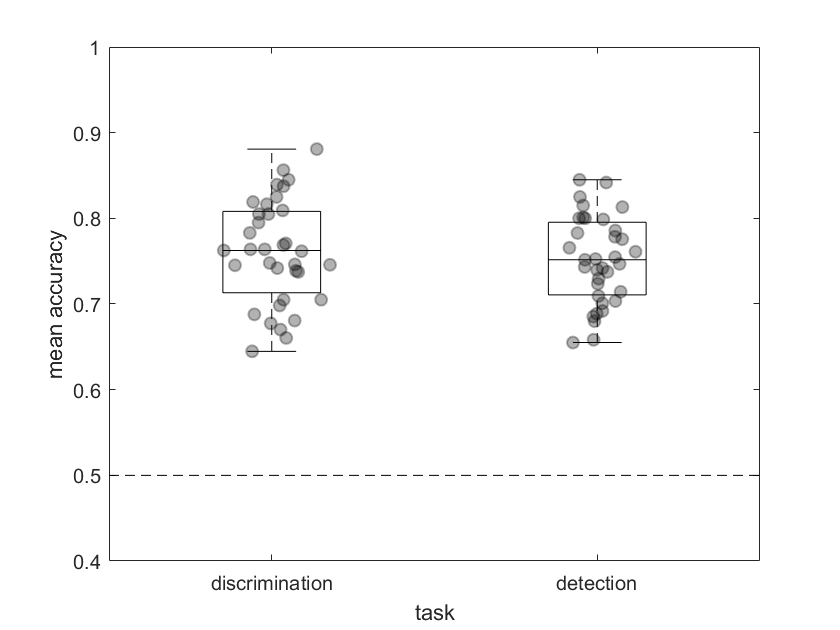


% fig = gcf;
% s=hgexport('readstyle','presentation');
% s.Format = 'png'; 
% s.Width = 20;
% s.Height = 20;
% hgexport(fig,'figures/behaviourCombined',s);

figure; hold on;
noise1 = normrnd(0,0.05,1,35);
noise2 = normrnd(0,0.05,1,35);
% plot([ones(1,35)+noise1; 2*ones(1,35)+noise2],[meanAccDis;meanAccDet],'color',[0.5,0.5,0.5]);
h=boxplot([meanAccDis;meanAccDet]','Colors','k');
scatter(ones(35,1)+noise1',meanAccDis,[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1, 'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(2*ones(35,1)+noise2',meanAccDet,[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
ylabel('mean accuracy');
xlim([0.5,2.5]); xlabel('task');
ylim([0.4,1]);
plot([0.5,2.5],[0.5,0.5],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'discrimination','detection'})